# Time Series PROJECT

## Task 

Construct 1-quarter-ahead forecasts of log(GDPC1), using a rolling window estimation scheme of 100 observations (= training set) for a total of $P=134$ forecasts

- Training Set: 101 obs

- First forecast origin is $R=1985:\textrm{Q2}$    (101)

- Last forecast origin is $T=2018:\textrm{Q3}$    (234)

Forecast evaluation is carried out comparing forecasts for the level (exp(log)) with GDPC1 and computing the RMSE (root mean squared error).

% Import data from spreadsheet
DatiProject = readtimetable("/Users/beatricecagnin/Documents/MATLAB/DatiProject.xlsx", "RowTimes", "Time");

% Display results
DatiProject % original name of the dataset

DatiProject = 254×4 timetable
       Time        GDPC1     PCECTPI    TB3MS      GS10 
    ___________    ______    _______    ______    ______

    30-Jun-1960    3430.1    15.331       3.54    4.5033
    30-Sep-1960    3439.8    15.415       4.23    4.5833
    30-Dec-1960    3517.2    15.435     3.8733    4.4867
    30-Mar-1961    3498.2    15.515     2.9933      4.26
    30-Jun-1961    3515.4    15.574       2.36    3.8333
    30-Sep-1961    3470.3    15.642     2.3067    3.8867
    30-Dec-1961    3493.7    15.671       2.35    3.7867
    30-Mar-1962      3553     15.67     2.3033      3.79
    30-Jun-1962    3621.3    15.726     2.3033      3.98
    30-Sep-

**Data description:**

GDPC1 = Real Gross Domestic Product, 3 Decimal (Billions of Chained 2012 Dollars) --> is the inflation adjusted value of the goods and services produced by labor and property located in the United States

PCECTPI = Personal Consumption Expenditure: Chain-Type Price Index (Index 2009=100)

TB3MS = 3-Month Treasury Bill Secondary Market Rate (Percent)

GS10 = 10-Year Treasury Constant Maturity Rate (Percent)

DatiProject.Properties

ans =   TimetableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Time'  'Variables'}
           VariableNames: {'GDPC1'  'PCECTPI'  'TB3MS'  'GS10'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowTimes: [254×1 datetime]
               StartTime: 30-Jun-1960
              SampleRate: NaN
                TimeStep: 1q
                  Events: []
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


% log GDPC1 in appended in the dataset

DatiProject.log_GDPC1= log(DatiProject.GDPC1)

DatiProject = 254×5 timetable
       Time        GDPC1     PCECTPI    TB3MS      GS10     log_GDPC1
    ___________    ______    _______    ______    ______    _________

    30-Jun-1960    3430.1    15.331       3.54    4.5033     8.1403  
    30-Sep-1960    3439.8    15.415       4.23    4.5833     8.1432  
    30-Dec-1960    3517.2    15.435     3.8733    4.4867     8.1654  
    30-Mar-1961    3498.2    15.515     2.9933      4.26       8.16  
    30-Jun-1961    3515.4    15.574       2.36    3.8333     8.1649  
    30-Sep-1961    3470.3    15.642     2.3067    3.8867      8.152  
    30-Dec-1961    3493.7    15.671       2.35    3.7867     8.1587  
    30-M

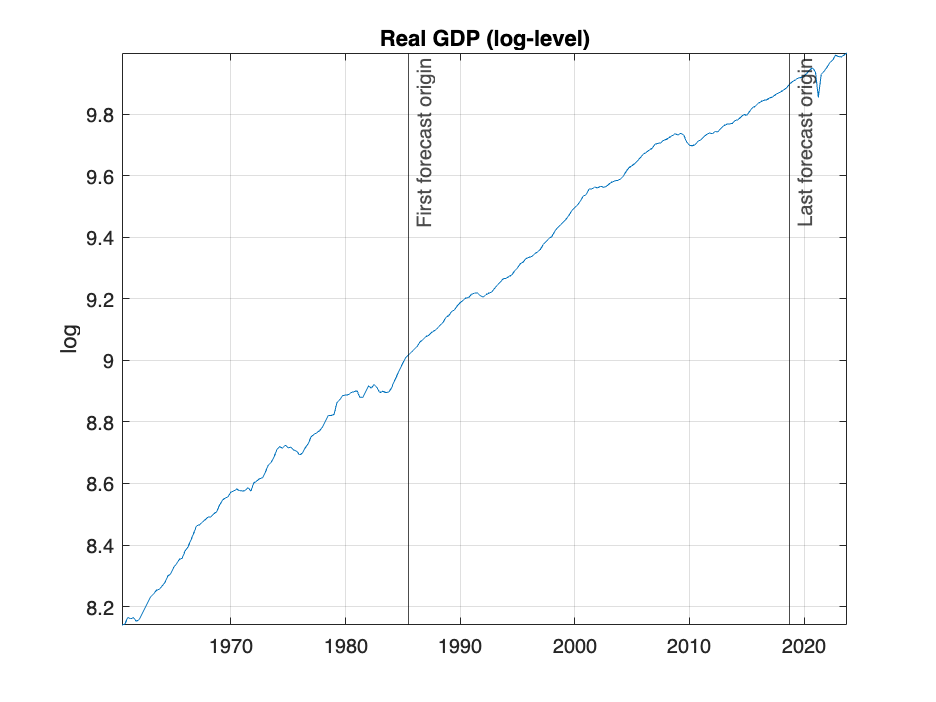

% plot data


plot(DatiProject.Time, DatiProject.log_GDPC1);

xline(datetime("1985-06-30"), '-k', 'First forecast origin');
xline(datetime("2018-09-30"), '-k', 'Last forecast origin');

title('Real GDP (log-level)'); ylabel('log'); axis tight; grid on

**To compute FORECASTS**

% SAMPLE = training (estimation) set + test (evaluation) set

sample = timerange('1960-06-30', '2018-12-30', 'closed')

sample = 	timetable timerange subscript:

		Select timetable rows with times in the closed interval:
		[30-Jun-1960 00:00:00, 30-Dec-2018 00:00:00]

	See Select Times in Timetable.


DatiProject1 = DatiProject(sample,:) % dataset d'interesse

DatiProject1 = 235×5 timetable
       Time        GDPC1     PCECTPI    TB3MS      GS10     log_GDPC1
    ___________    ______    _______    ______    ______    _________

    30-Jun-1960    3430.1    15.331       3.54    4.5033     8.1403  
    30-Sep-1960    3439.8    15.415       4.23    4.5833     8.1432  
    30-Dec-1960    3517.2    15.435     3.8733    4.4867     8.1654  
    30-Mar-1961    3498.2    15.515     2.9933      4.26       8.16  
    30-Jun-1961    3515.4    15.574       2.36    3.8333     8.1649  
    30-Sep-1961    3470.3    15.642     2.3067    3.8867      8.152  
    30-Dec-1961    3493.7    15.671       2.35    3.7867     8.1587  
    30-

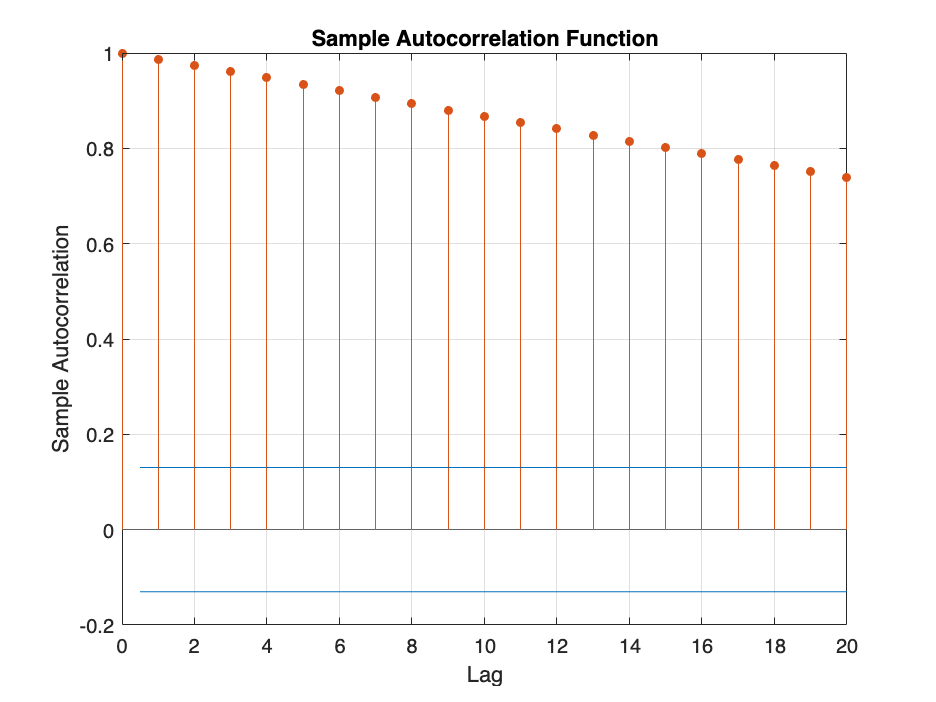

autocorr(DatiProject1.log_GDPC1);        % ACF of y(t)

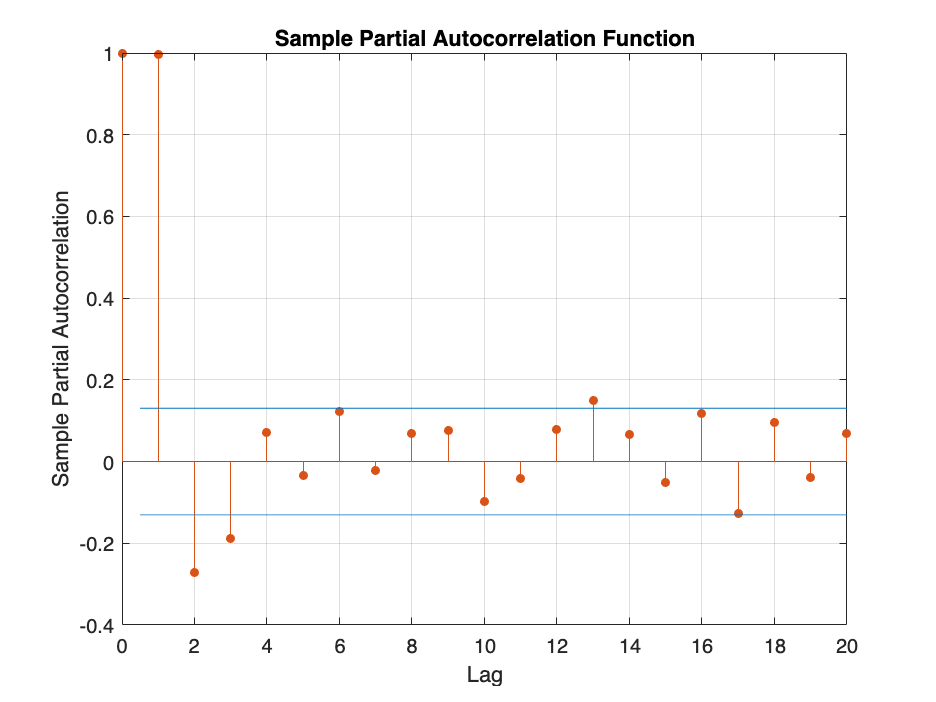

parcorr(DatiProject1.log_GDPC1);        % PACF of y(t)

% Dy(t) 

Dy_t = diff(DatiProject.log_GDPC1)

Dy_t =     0.0028
    0.0222
   -0.0054
    0.0049
   -0.0129
    0.0067
    0.0168
    0.0190
    0.0194
    0.0177


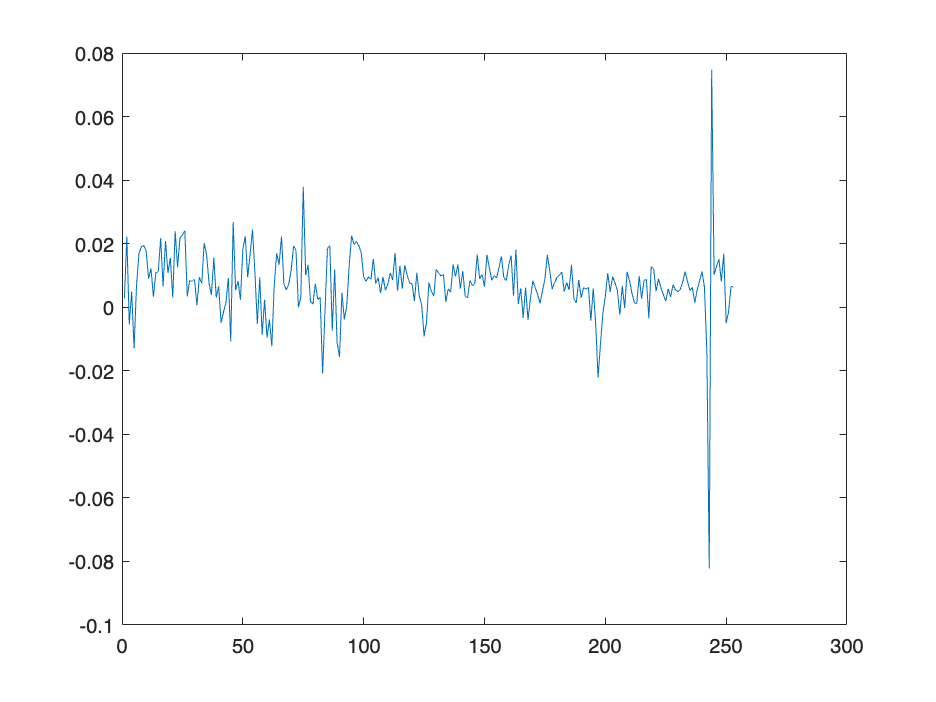

plot(Dy_t)

sample2 = timerange('1960-06-30', '2018-12-30', 'closed');     % T = training + test set
DatiProject2 = DatiProject(sample2,:)

DatiProject2 = 235×5 timetable
       Time        GDPC1     PCECTPI    TB3MS      GS10     log_GDPC1
    ___________    ______    _______    ______    ______    _________

    30-Jun-1960    3430.1    15.331       3.54    4.5033     8.1403  
    30-Sep-1960    3439.8    15.415       4.23    4.5833     8.1432  
    30-Dec-1960    3517.2    15.435     3.8733    4.4867     8.1654  
    30-Mar-1961    3498.2    15.515     2.9933      4.26       8.16  
    30-Jun-1961    3515.4    15.574       2.36    3.8333     8.1649  
    30-Sep-1961    3470.3    15.642     2.3067    3.8867      8.152  
    30-Dec-1961    3493.7    15.671       2.35    3.7867     8.1587  
    30-

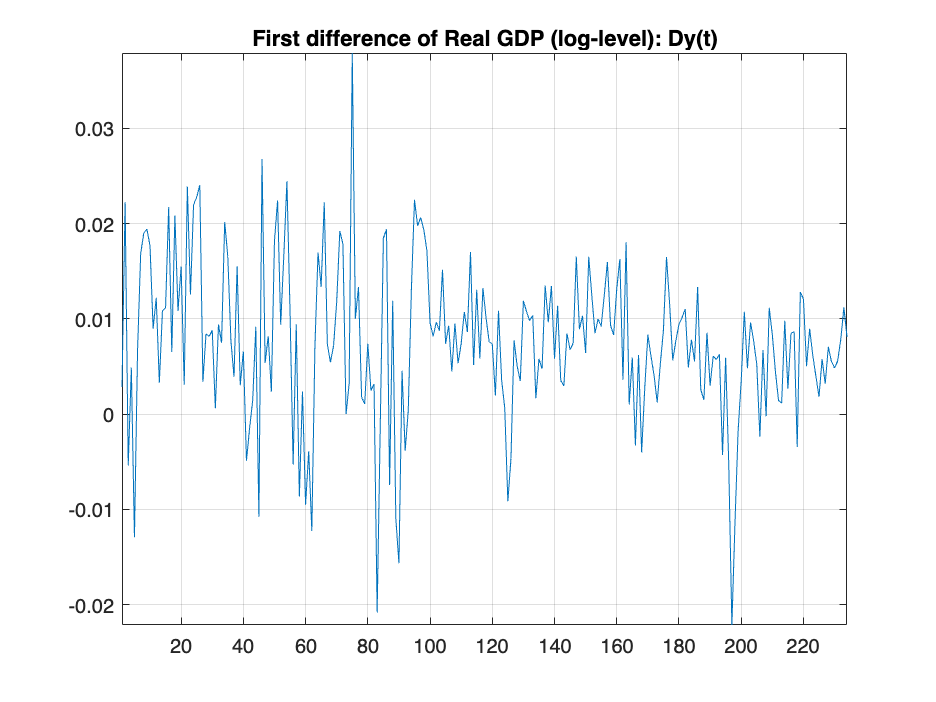

Dlog_GDPC1 = diff(DatiProject2.log_GDPC1);   % first difference of our dataset 235 x 5
plot(Dlog_GDPC1);
title('First difference of Real GDP (log-level): Dy(t)'); axis tight; grid on

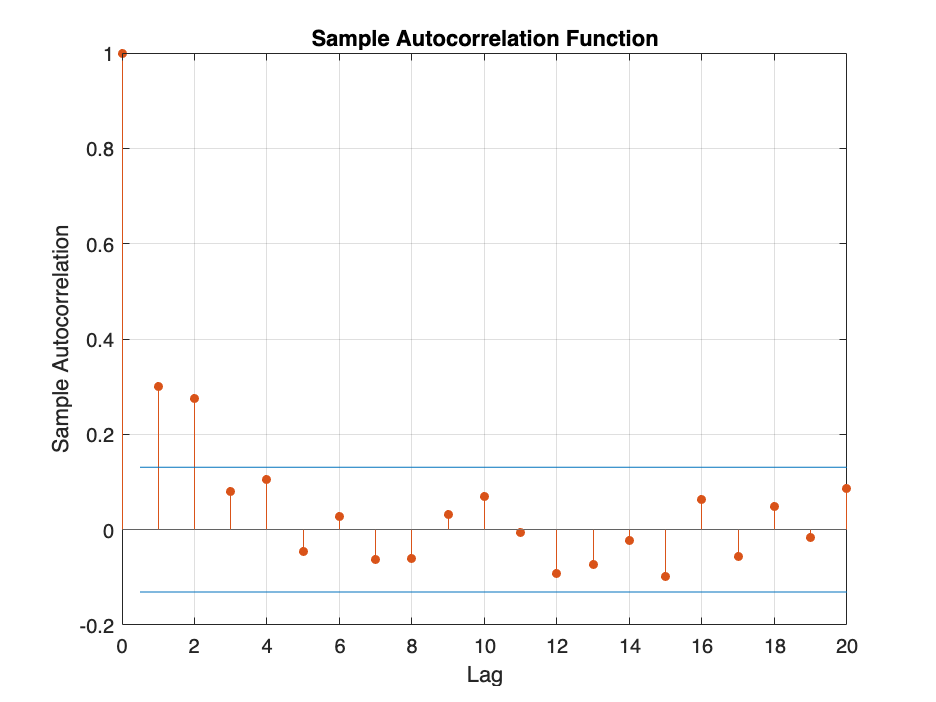

autocorr(Dlog_GDPC1);         % ACF of Dy(t)

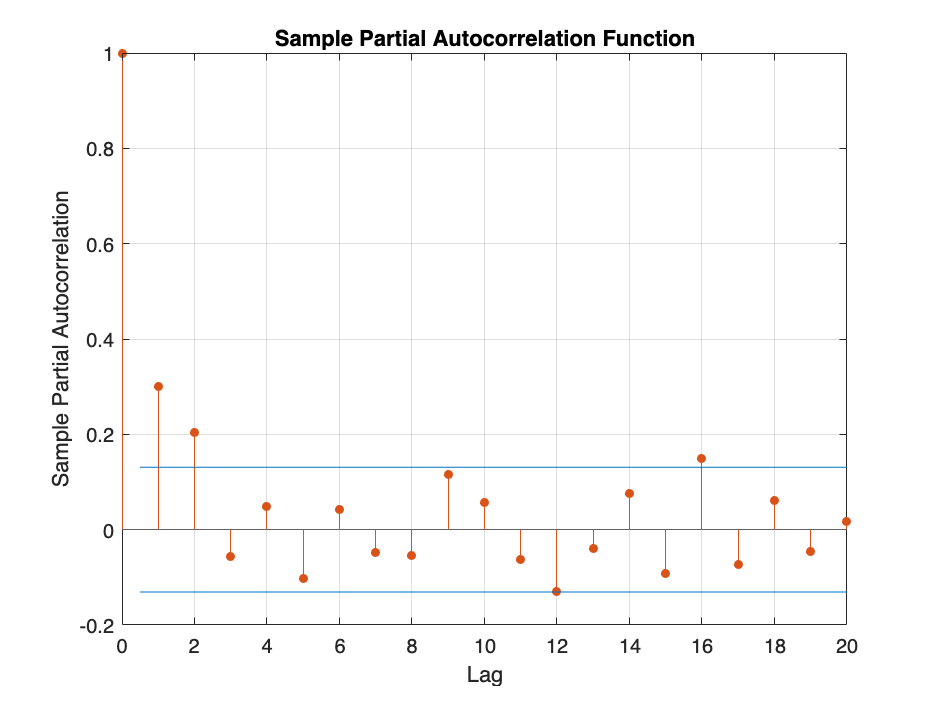

parcorr(Dlog_GDPC1);           % PACF of Dy(t)

% sample size
T = size(DatiProject1, 1);
% training set (estimation) and Test set (evaluation)
time = DatiProject1.Time;

id1 = datetime(time) < datetime('1985-06-30'); % returns 1 for training set and 0 for test set
y = DatiProject.log_GDPC1(id1);   % is the log-p estimation sample


## MODELS

**1) RANDOM WALK (without drift) / Naive / No change forecast**

"the best available forecast for tomorrow is today": at each point in time t, the value of the series is the result of all shocks that have hit $p_t$

considering $p_t =\log \left(P_t \right)$,

RW forecast for log-prices is

$p_t =p_{t-1} +u_t$        $u_t \sim N\left(0,\sigma^2 \right)$ Gaussian White Noise Errors (no autocorrelation)

This is equivalent to specifying a zero-mean arima model for returns:

It implies that returns $r_t =p_t -p_{t-1} \;$with $p_t =\log \left(P_t \right)$ have mean 0 and variance $\sigma^2$


$$p_t -p_{t-1} =u_t$$
        
$$u_t \sim N\left(0,\sigma^2 \right)$$
 

The RW forecast is also known as no-change forecast because it implies forecast of returns (first differences) equal to zero.

This is equivalent to specifying a zero-mean arima model for returns:

m1 = arima('D', 1, 'Constant', 0)

m1 =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: 0
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

% m1 = estimate(m1, y);

## Rolling scheme: from jj-100+1 to T

T = length(DatiProject1.log_GDPC1);
T0 = 101;
h = 1;
fore1 = NaN(T,h);
jj = T0;
while jj < T 
    m1 = estimate(m1,DatiProject1.log_GDPC1(jj-100:jj), 'Display','off');       % estimate
    fore1(jj+1) = forecast(m1, h, DatiProject1.log_GDPC1(jj-100:jj));   % forecast
    jj = jj+1
end;

jj = 102

jj = 103

jj = 104

jj = 105

jj = 106

jj = 107

jj = 108

jj = 109

jj = 110

jj = 111

jj = 112

jj = 113

jj = 114

jj = 115

jj = 116

jj = 117

jj = 118

jj = 119

jj = 120

jj = 121

jj = 122

jj = 123

jj = 124

jj = 125

jj = 126

jj = 127

jj = 128

jj = 129

jj = 130

jj = 131

jj = 132

jj = 133

jj = 134

jj = 135

jj = 136

jj = 137

jj = 138

jj = 139

jj = 140

jj = 141

jj = 142

jj = 143

jj = 144

jj = 145

jj = 146

jj = 147

jj = 148

jj = 149

jj = 150

jj = 151

jj = 152

jj = 153

jj = 154

jj = 155

jj = 156

jj = 157

jj = 158

jj = 159

jj = 160

jj = 161

jj = 162

jj = 163

jj = 164

jj = 165

jj = 166

jj = 167

jj = 168

jj = 169

jj = 170

jj = 171

jj = 172

jj = 173

jj = 174

jj = 175

jj = 176

jj = 177

jj = 178

jj = 179

jj = 180

jj = 181

jj = 182

jj = 183

jj = 184

jj = 185

jj = 186

jj = 187

jj = 188

jj = 189

jj = 190

jj = 191

jj = 192

jj = 193

jj = 194

jj = 195

jj = 196

jj = 197

jj = 198

jj = 199

jj = 200

jj = 201

jj = 202

jj = 203

jj = 204

jj = 205

jj = 206

jj = 207

jj = 208

jj = 209

jj = 210

jj = 211

jj = 212

jj = 213

jj = 214

jj = 215

jj = 216

jj = 217

jj = 218

jj = 219

jj = 220

jj = 221

jj = 222

jj = 223

jj = 224

jj = 225

jj = 226

jj = 227

jj = 228

jj = 229

jj = 230

jj = 231

jj = 232

jj = 233

jj = 234

jj = 235


$$\textrm{RMSE}=\sqrt{\frac{1}{T}\sum \hat{{u_h }^2 } }$$


% rmse = mean((A-F).^2).^0.5
DatiProject11 = DatiProject.GDPC1(102:235);
forecasts1 = exp(fore1(102:235));

rmse1 = mean((DatiProject11-forecasts1).^2).^0.5

rmse1 = 120.0598

nanValue = NaN(101,1)

nanValue =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


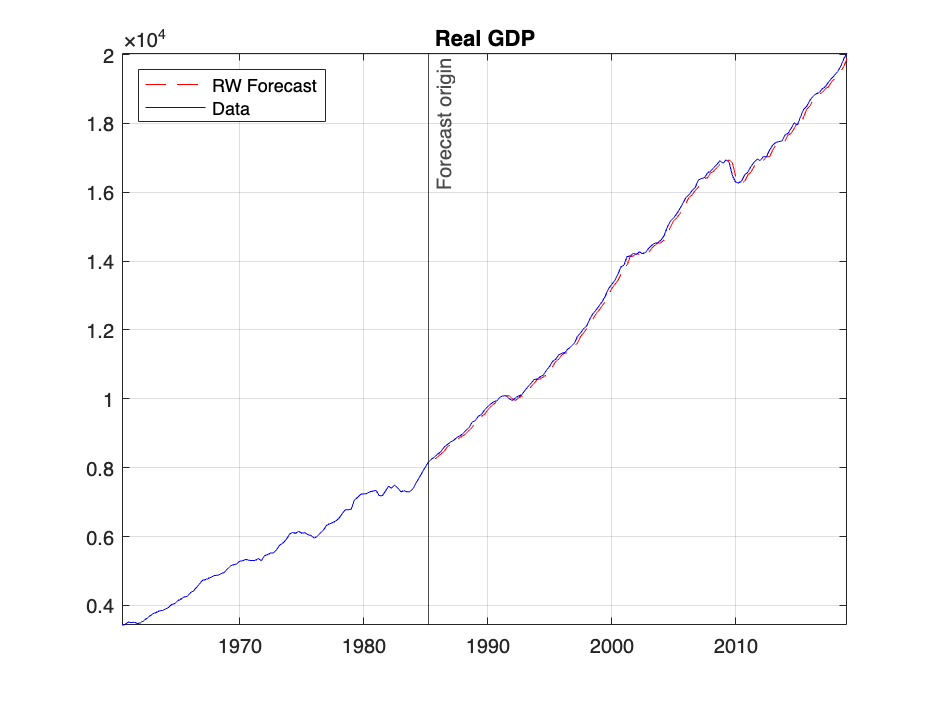

forecasts1 = [nanValue;forecasts1];
plot(time, forecasts1, '--r'); hold on;
plot(time, DatiProject1.GDPC1, '-b'); hold off
xline(datetime("1985-03-30"), '-k', 'Forecast origin');

title('Real GDP'); axis tight; grid on
legend('RW Forecast', 'Data', 'Location','northwest')

xlim([datetime(1960,6,30)...
      datetime(2018,12,30)])

**2) AR(4)**

m2 = arima(4,1,0)

m2 =   arima with properties:

     Description: "ARIMA(4,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 5
               D: 1
               Q: 0
        Constant: NaN
              AR: {NaN NaN NaN NaN} at lags [1 2 3 4]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

m2 = estimate(m2, y)

 
    ARIMA(4,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0053445      0.0014403         3.7107     0.00020665
    AR{1}          0.23589        0.11568         2.0392       0.041429
    AR{2}          0.19569       0.097896          1.999       0.045607
    AR{3}         -0.10291        0.12009       -0.85697        0.39146
    AR{4}         0.069476       0.094763        0.73315        0.46347
    Variance    9.9759e-05     1.3587e-05         7.3425     2.0968e-13



m2 =   arima with properties:

     Description: "ARIMA(4,1,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 5
               D: 1
               Q: 0
        Constant: 0.00534454
              AR: {0.235888 0.195695 -0.102912 0.0694756} at lags [1 2 3 4]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 9.97588e-05

fore2 = NaN(T,h);
jj = T0;
while jj < T
    m2 = estimate(m2,DatiProject1.log_GDPC1(jj-100:jj), 'Display', 'off'); % estimate
    % forecast
    fore2(jj+1) = forecast(m2, h, DatiProject1.log_GDPC1(jj-100:jj));
    jj = jj+1
end;

jj = 102

jj = 103

jj = 104

jj = 105

jj = 106

jj = 107

jj = 108

jj = 109

jj = 110

jj = 111

jj = 112

jj = 113

jj = 114

jj = 115

jj = 116

jj = 117

jj = 118

jj = 119

jj = 120

jj = 121

jj = 122

jj = 123

jj = 124

jj = 125

jj = 126

jj = 127

jj = 128

jj = 129

jj = 130

jj = 131

jj = 132

jj = 133

jj = 134

jj = 135

jj = 136

jj = 137

jj = 138

jj = 139

jj = 140

jj = 141

jj = 142

jj = 143

jj = 144

jj = 145

jj = 146

jj = 147

jj = 148

jj = 149

jj = 150

jj = 151

jj = 152

jj = 153

jj = 154

jj = 155

jj = 156

jj = 157

jj = 158

jj = 159

jj = 160

jj = 161

jj = 162

jj = 163

jj = 164

jj = 165

jj = 166

jj = 167

jj = 168

jj = 169

jj = 170

jj = 171

jj = 172

jj = 173

jj = 174

jj = 175

jj = 176

jj = 177

jj = 178

jj = 179

jj = 180

jj = 181

jj = 182

jj = 183

jj = 184

jj = 185

jj = 186

jj = 187

jj = 188

jj = 189

jj = 190

jj = 191

jj = 192

jj = 193

jj = 194

jj = 195

jj = 196

jj = 197

jj = 198

jj = 199

jj = 200

jj = 201

jj = 202

jj = 203

jj = 204

jj = 205

jj = 206

jj = 207

jj = 208

jj = 209

jj = 210

jj = 211

jj = 212

jj = 213

jj = 214

jj = 215

jj = 216

jj = 217

jj = 218

jj = 219

jj = 220

jj = 221

jj = 222

jj = 223

jj = 224

jj = 225

jj = 226

jj = 227

jj = 228

jj = 229

jj = 230

jj = 231

jj = 232

jj = 233

jj = 234

jj = 235

% rmse = mean((A-F).^2).^0.5
DatiProject11 = DatiProject.GDPC1(102:235);
forecasts2 = exp(fore2(102:235));

rmse2 = mean((DatiProject11-forecasts2).^2).^0.5

rmse2 = 80.3816

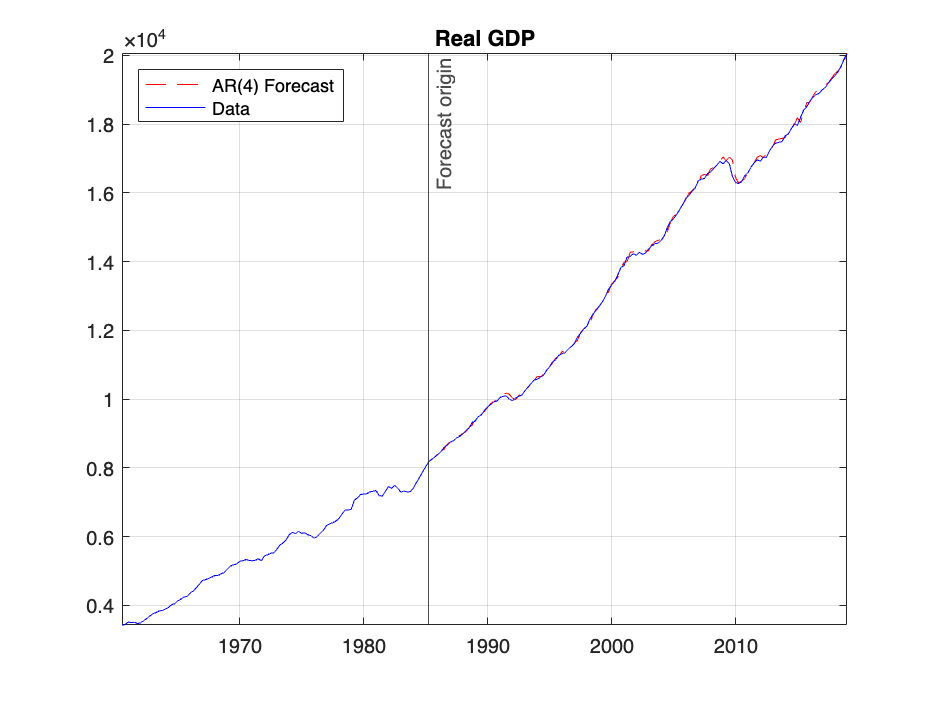

forecasts2 = [nanValue;forecasts2];
plot(time, forecasts2, '--r'); hold on;
plot(time, DatiProject1.GDPC1, '-b'); hold off
xline(datetime("1985-03-30"), '-k', 'Forecast origin');

title('Real GDP'); axis tight; grid on
legend('AR(4) Forecast', 'Data', 'Location','northwest')

xlim([datetime(1960,6,30)...
      datetime(2018,12,30)])

**3) VAR(4): **		

Vector Autoregressive Models of order 4

% Dy(t)
Dy_t

Dy_t =     0.0028
    0.0222
   -0.0054
    0.0049
   -0.0129
    0.0067
    0.0168
    0.0190
    0.0194
    0.0177


% π(t) = log(PCECTPIt)−logPCECTPIy−1
log_PCECTPI = log(DatiProject.PCECTPI)

log_PCECTPI =     2.7299
    2.7353
    2.7366
    2.7418
    2.7456
    2.7500
    2.7518
    2.7517
    2.7553
    2.7564


pi_t = diff(log_PCECTPI)  %pi_t = log_PCECTPI - lagmatrix(log_PCECTPI, 1)

pi_t =     0.0055
    0.0013
    0.0052
    0.0038
    0.0044
    0.0019
   -0.0001
    0.0036
    0.0011
    0.0043


% TSpread
Tspread_t = DatiProject.GS10 - DatiProject.TB3MS

Tspread_t =     0.9633
    0.3533
    0.6134
    1.2667
    1.4733
    1.5800
    1.4367
    1.4867
    1.6767
    1.5133


Tspread_t = Tspread_t(2:254)

Tspread_t =     0.3533
    0.6134
    1.2667
    1.4733
    1.5800
    1.4367
    1.4867
    1.6767
    1.5133
    1.2934


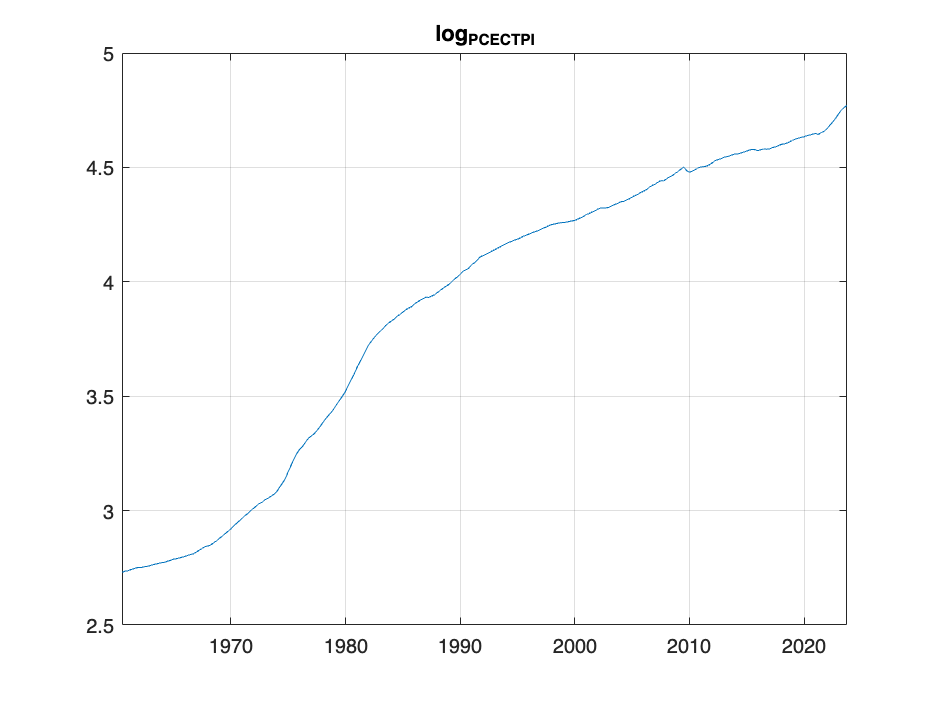

plot(DatiProject.Time, log_PCECTPI)    % ref. section 1
title('log_PCECTPI'); grid on

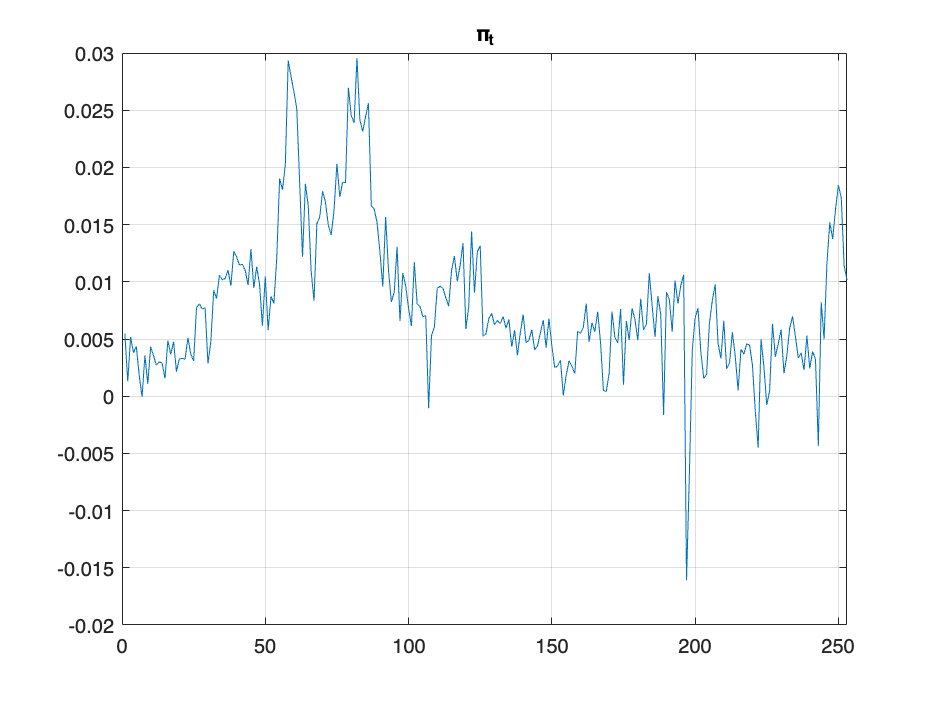

plot(pi_t)    % ref. section 1
title('π_t'); grid on

xlim([0 253])
ylim([-0.0200 0.0300])

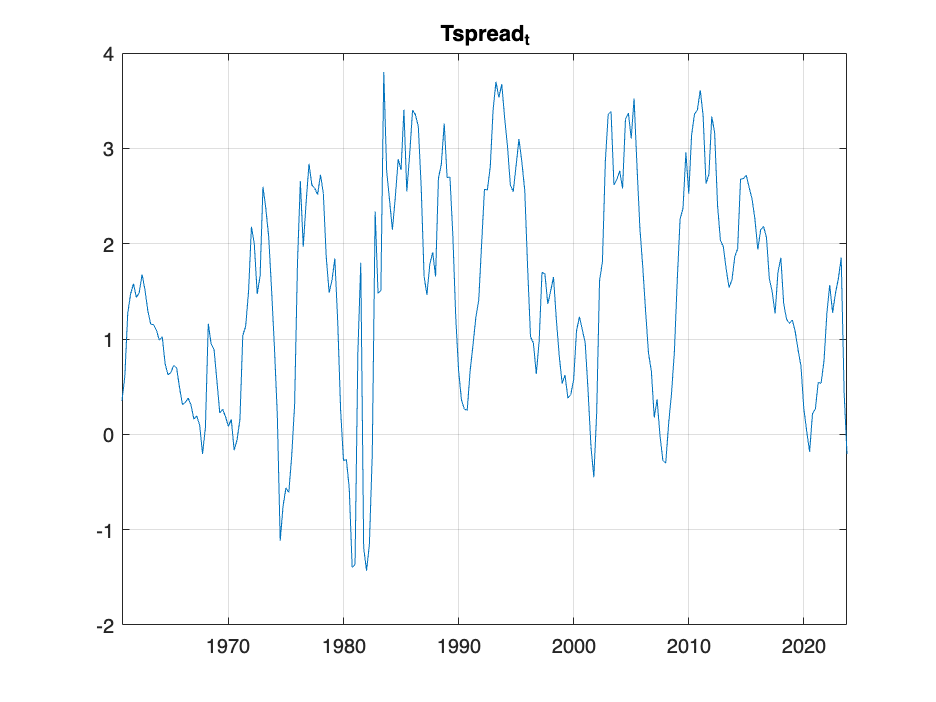

plot(DatiProject.Time(2:254), Tspread_t)    % ref. section 1
title('Tspread_t'); grid on

VAR(4)

Estimation of VAR model: estimate a VAR model (varm command) for ∆yt,πt, Tspreadt. 

In this case the command forecast produces forecast for the first difference of log-GDP (in column 1, if variables are ordered as above). 

To get a forecast for the log-GDP use the fact that:


$$\Delta {\hat{y} }_{T+1|T} ={\hat{y} }_{T+1|T} -y_T \;\;\;\;\;\;\;\;\;\leftrightarrow {\;\;\;\;\;\;\;\;\;\hat{y} }_{T+1|T} =y_T +\Delta {\hat{y} }_{T+1|T}$$


h = 1;

pmax = 4;

y_var = [Dy_t pi_t Tspread_t];

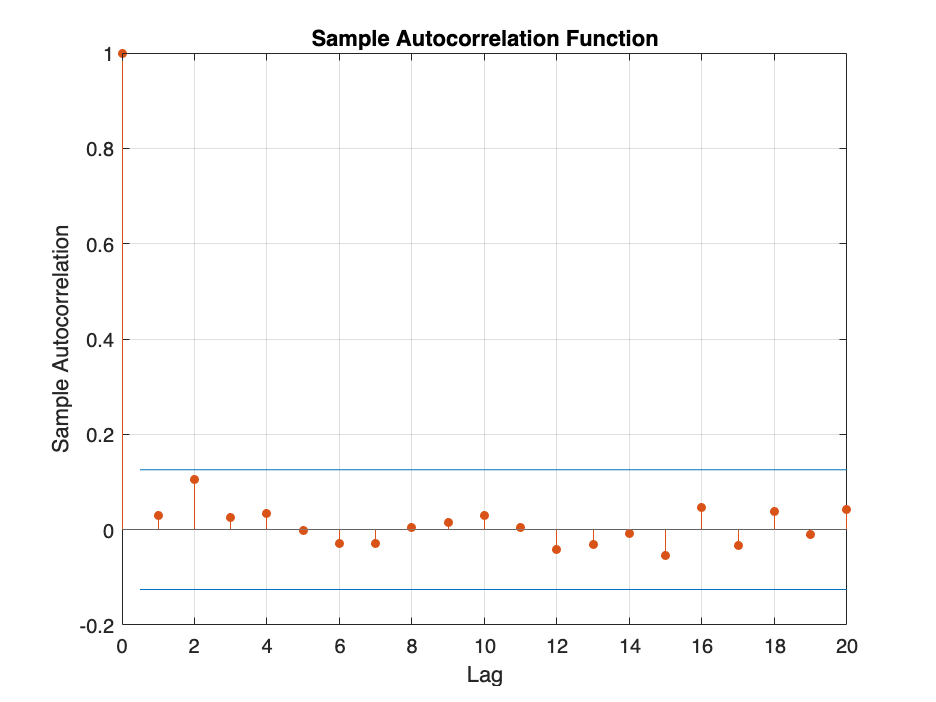

autocorr(Dy_t) % ref section 2

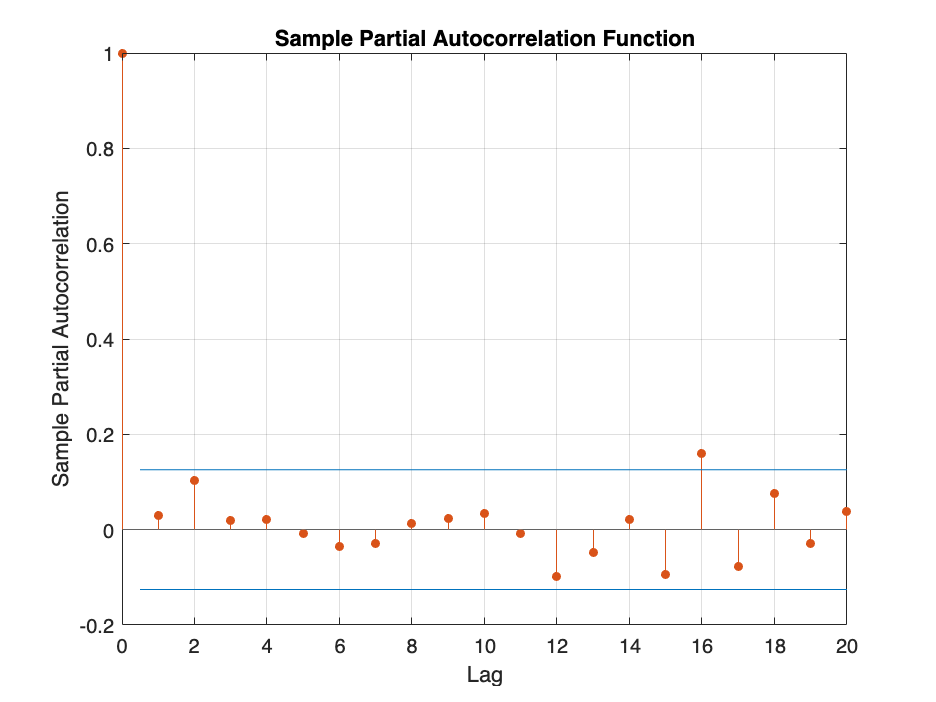

parcorr(Dy_t)    % ref section 2

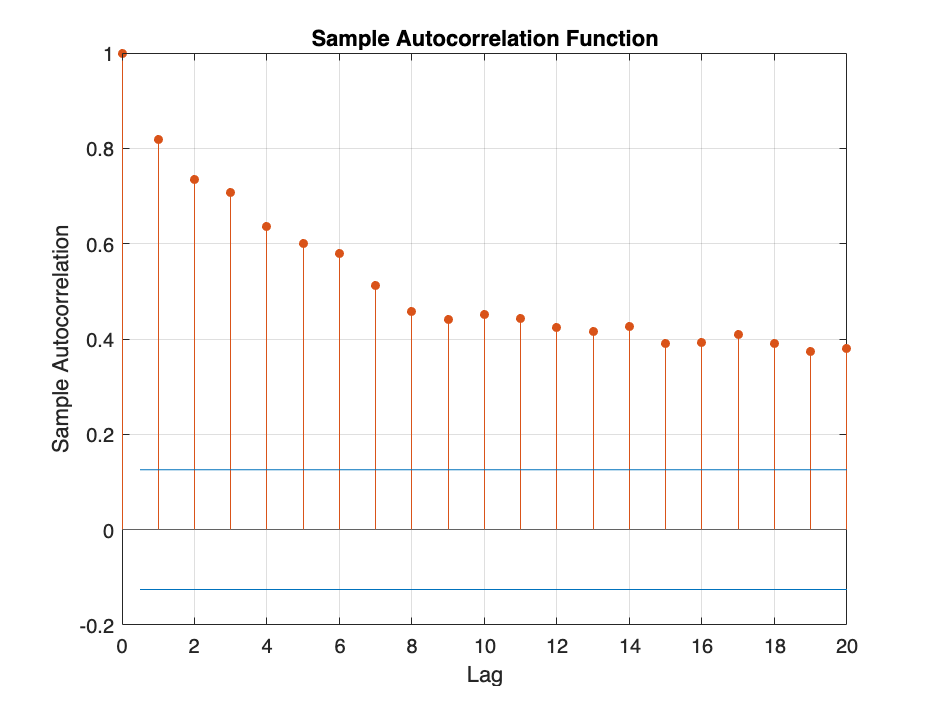

autocorr(pi_t)  % ref section 2

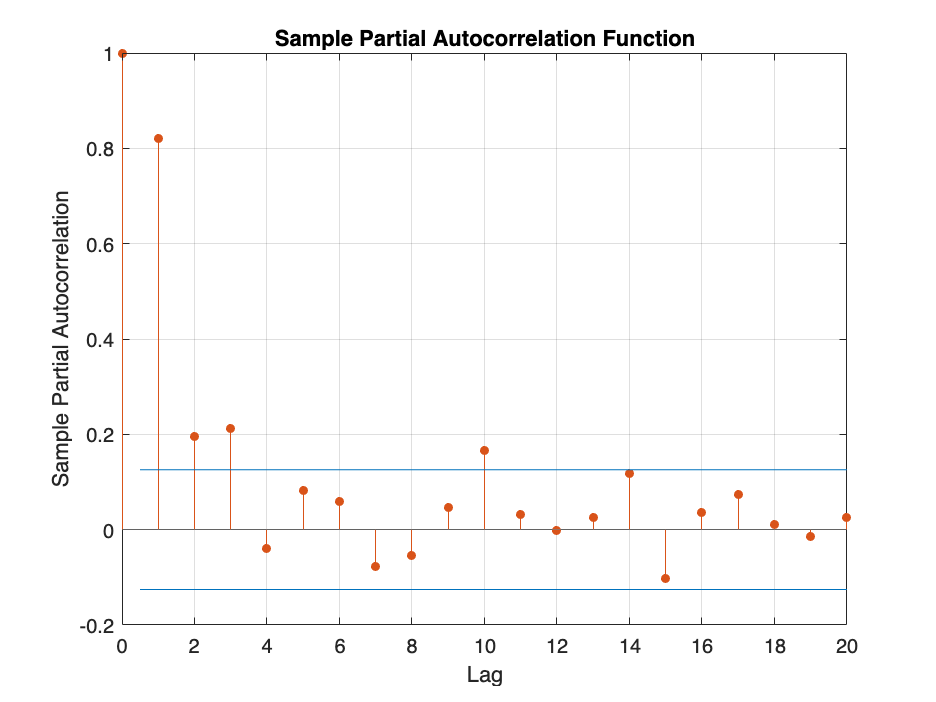

parcorr(pi_t)              % ref section 2

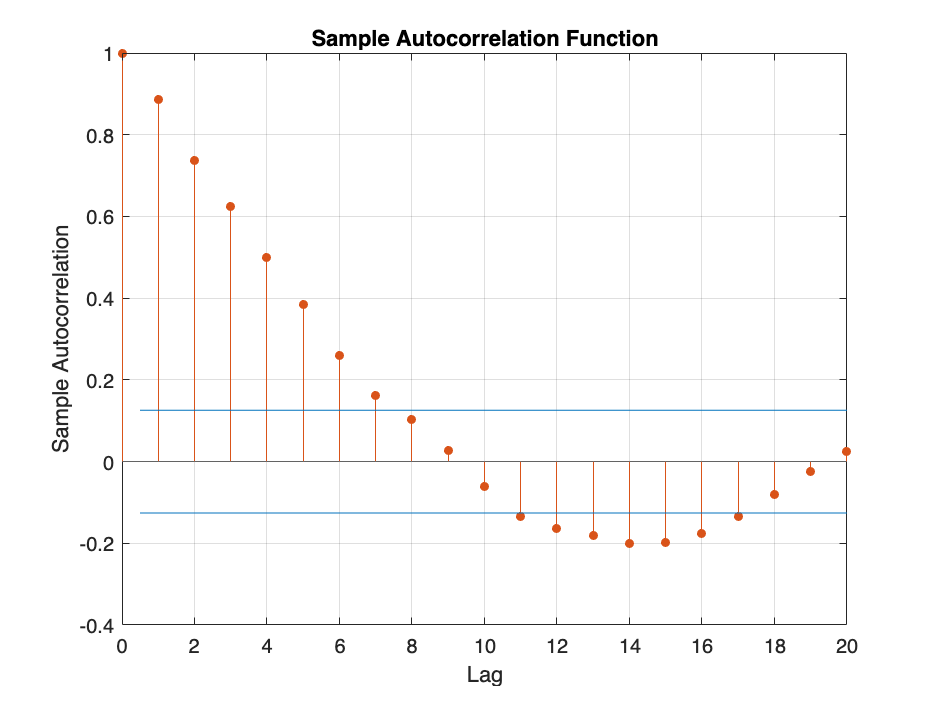

autocorr(Tspread_t)    % ref section 2

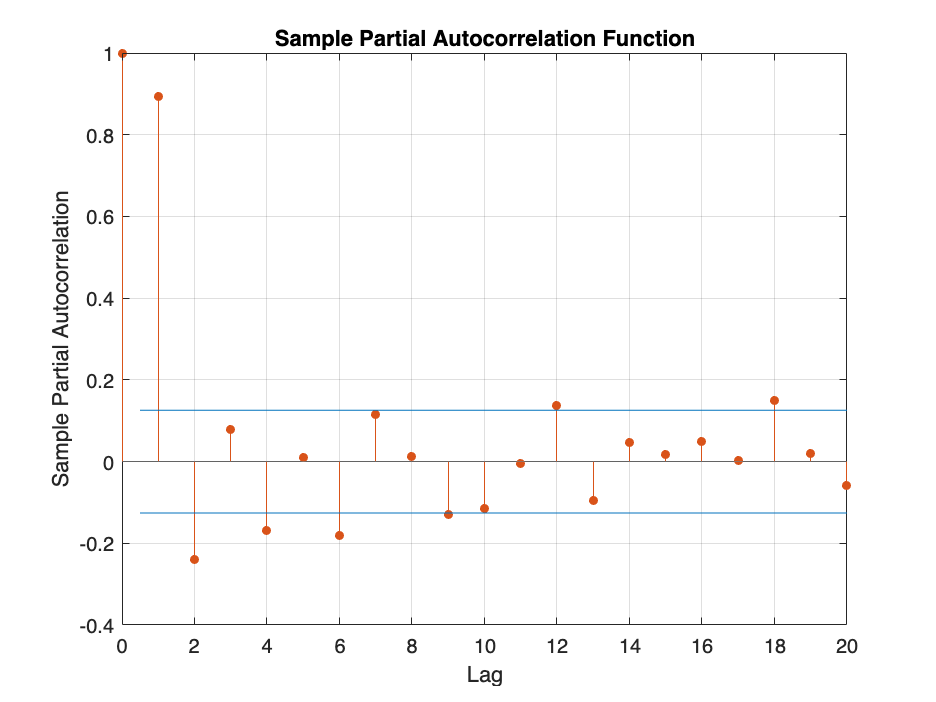

parcorr(Tspread_t) % section 2

log_GDPC1 = DatiProject.log_GDPC1;
fore33 = zeros(T, 3);
y = log_GDPC1(2:235);
fore3 = [];
jj = T0;
T = 234;
while jj < T % forecast loop
    % rolling window = 1000
   
    m3 = estimate(varm(3, 4), y_var(jj-100:jj, :),'Display', 'off'); % estimate
    % forecast
    fore33(jj+1,:) = forecast(m3, h, y_var(jj-100:jj, :));
    fore3 = [fore3; fore33(jj+1,1) + y(jj)];   % formula del prof nel loop
    jj = jj + 1;
end;

forecast3 = exp(fore3);  % i take the exponential value of the 133 forecasts
DatiProject111 = DatiProject11(2:134);

To get a forecast for the log-GDP use the fact that:

∆ŷT+1|T = ŷT+1|T - yt ↔ ŷT+1|T = yt + ∆ŷT+1|T

RMSE = mean((DatiProject111-forecast3).^2).^0.5 

RMSE = 92.9077

nanVector = NaN(102,1);
% Concatenate the vectors
forecasts = [nanVector; forecast3];

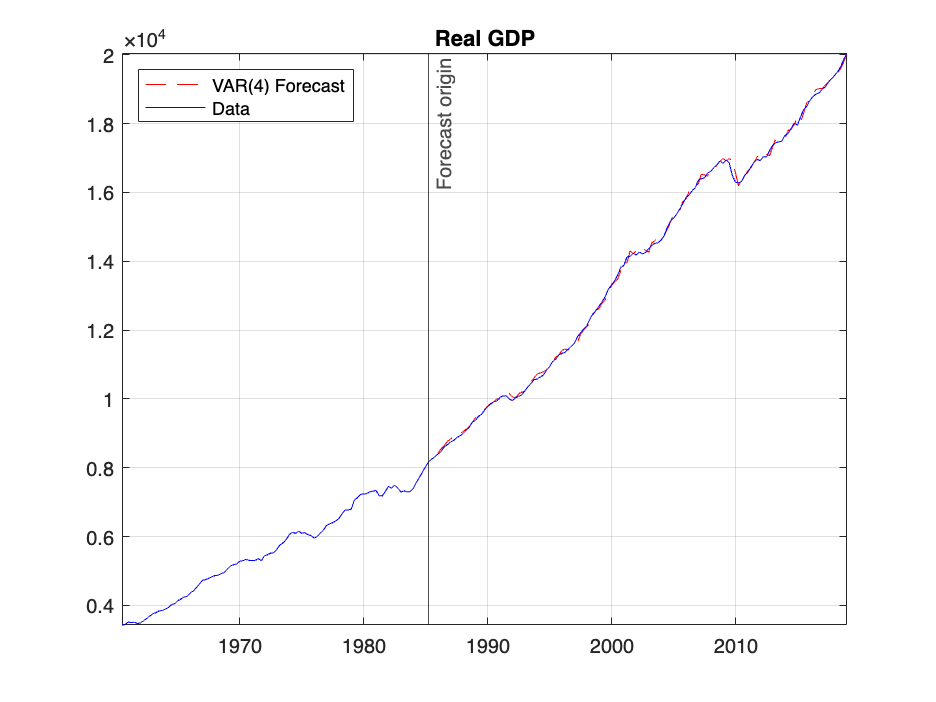

forecast3 = [nanVector;forecast3];
plot(time, forecast3, '--r'); hold on;
plot(time, DatiProject1.GDPC1, '-b'); hold off
xline(datetime("1985-03-30"), '-k', 'Forecast origin');

title('Real GDP'); axis tight; grid on
legend('VAR(4) Forecast', 'Data', 'Location','northwest')

xlim([datetime(1960,6,30)...
      datetime(2018,12,30)])

**4) VAR(p) model selected with AIC**

IC = NaN (12, 1);    
for ii = 1:12      
    mhat = estimate(varm(3, ii), y_var);
    tmp = summarize(mhat);
    IC(ii) = tmp.AIC;
end;

paic = find(min(IC) == IC) % it gives the minimum of AIC

paic = 2


m4 = varm(size(y_var, 2), paic)  % we define a new model using paic

m4 =   varm with properties:

     Description: "3-Dimensional VAR(2) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 2
        Constant: [3×1 vector of NaNs]
              AR: {3×3 matrices of NaNs} at lags [1 2]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix of NaNs]

log_GDPC1 = DatiProject.log_GDPC1;
fore44 = zeros(T, 3);
y = log_GDPC1(2:235);
p = log_PCECTPI(2:235);

fore4 = [];
fore5 = [];
fore6 =  [];
jj = T0;
T = 234;
while jj < T % forecast loop
    % rolling window = 1000
   
    m4 = estimate(varm(3, 2), y_var(jj-100:jj, :),'Display', 'off'); % estimate
    % forecast
    fore44(jj+1,:) = forecast(m4, h, y_var(jj-100:jj, :));
    fore4 = [fore4; fore44(jj+1,1) + y(jj)];   % formula del prof nel loop
    fore5 = [fore5; fore44(jj+1,2) + p(jj)];
    fore6 = [fore6; fore44(jj+1,3)];
    jj = jj + 1;
end;

forecast4 = exp(fore4);  % i take the exponential value of the 133 forecasts
RMSE4 = mean((DatiProject111-forecast4).^2).^0.5 

RMSE4 = 87.9803

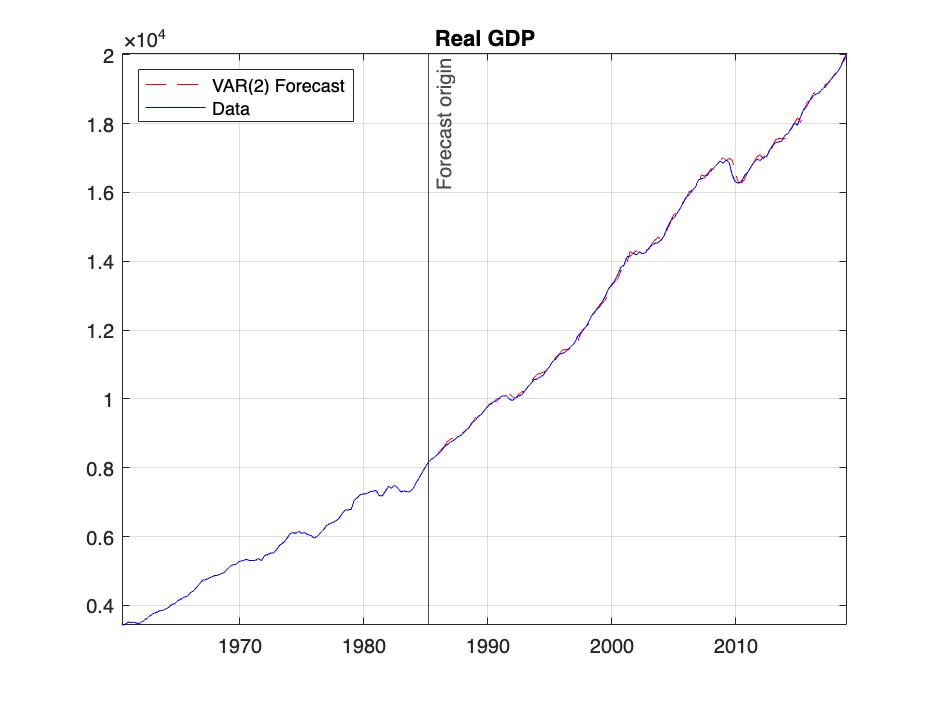

forecast44 = [nanVector;forecast4];
plot(time, forecast44, '--r'); hold on;
plot(time, DatiProject1.GDPC1, '-b'); hold off
xline(datetime("1985-03-30"), '-k', 'Forecast origin');

title('Real GDP');axis tight; grid on
legend('VAR(2) Forecast', 'Data', 'Location','northwest')

xlim([datetime(1960,6,30)...
      datetime(2018,12,30)])

Residuals (per i residui le prime due variabili GDP, PCECTPI ho preso i valori reali, cioè non in log.

uhat_real_GDP = DatiProject111 - forecast4;

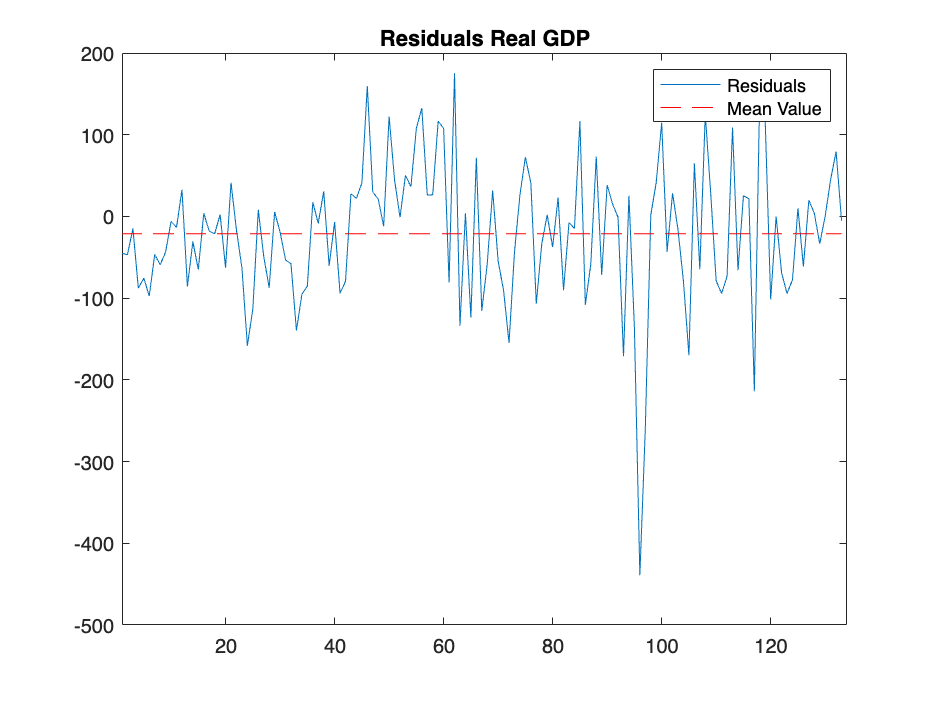

plot(uhat_real_GDP); title('Residuals Real GDP');  hold on % ref section 2
xlim([1 134]);
meanValue1 = mean(uhat_real_GDP);
line([1, length(uhat_real_GDP)], [meanValue1, meanValue1], 'Color', 'red', 'LineStyle', '--'); % a line for the mean of the residuals
legend('Residuals', 'Mean Value');
hold off;

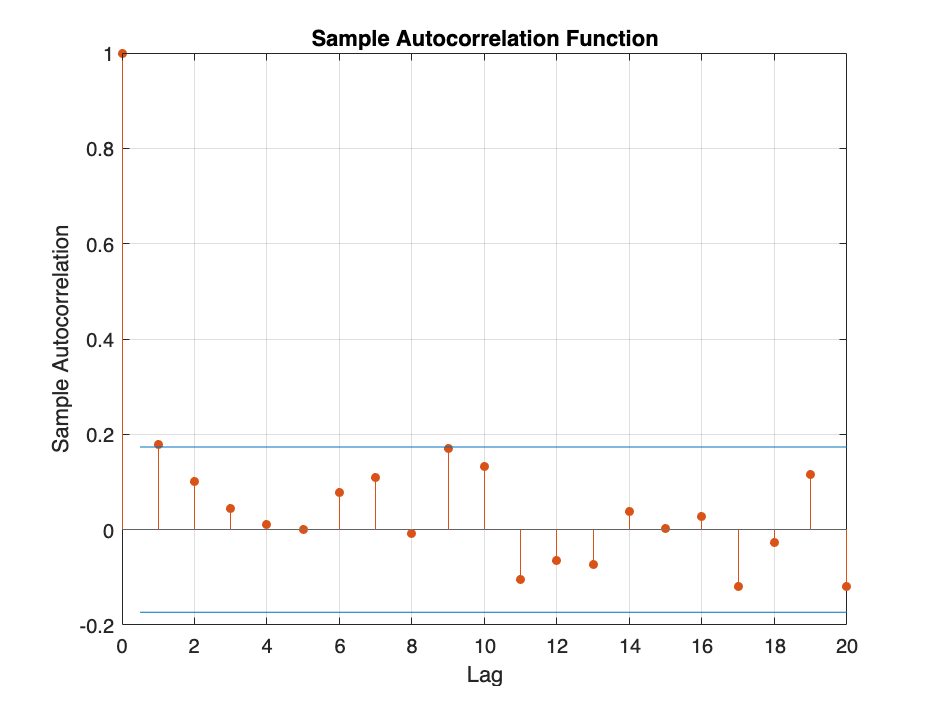

autocorr(uhat_real_GDP);

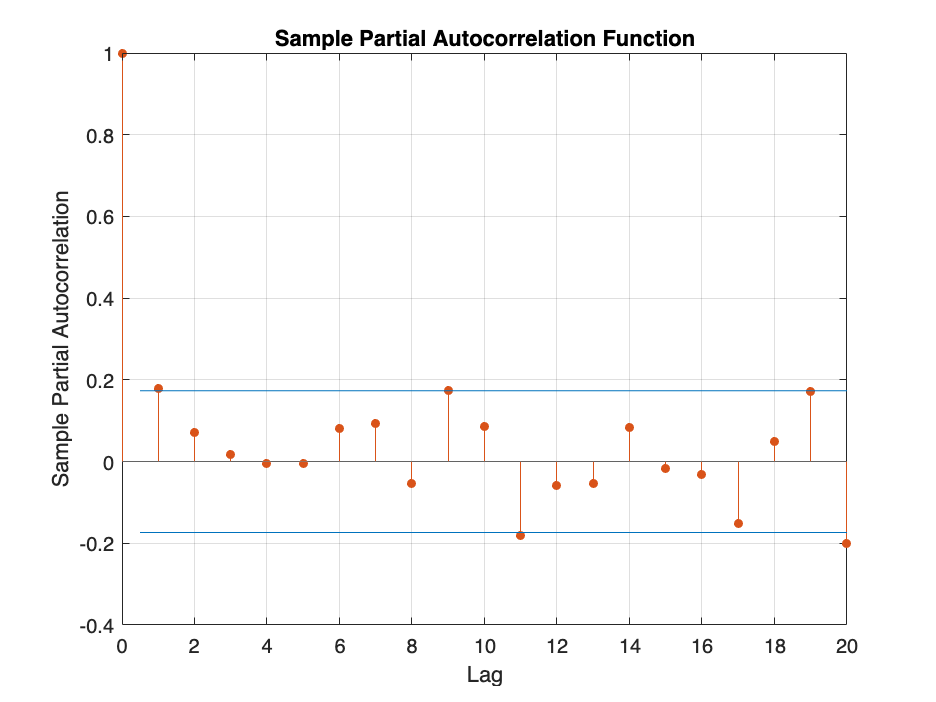

parcorr(uhat_real_GDP)

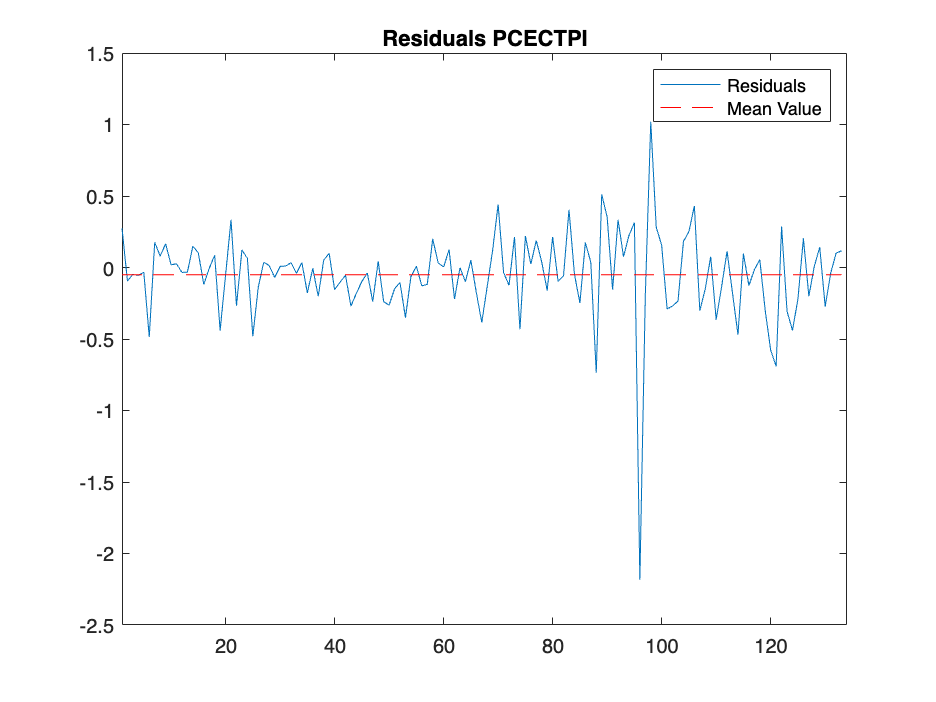

forecast5 = exp(fore5);
DatiProject222 = DatiProject.PCECTPI(103:235);
uhat_PCECTPI = DatiProject222 - forecast5;
meanValue2 = mean(uhat_PCECTPI);
plot(uhat_PCECTPI); title('Residuals PCECTPI'); hold on    % ref section 2
xlim([1 134]);
line([1, length(uhat_PCECTPI)], [meanValue2, meanValue2], 'Color', 'red', 'LineStyle', '--'); hold off % a line for the mean of the residuals
legend('Residuals', 'Mean Value');

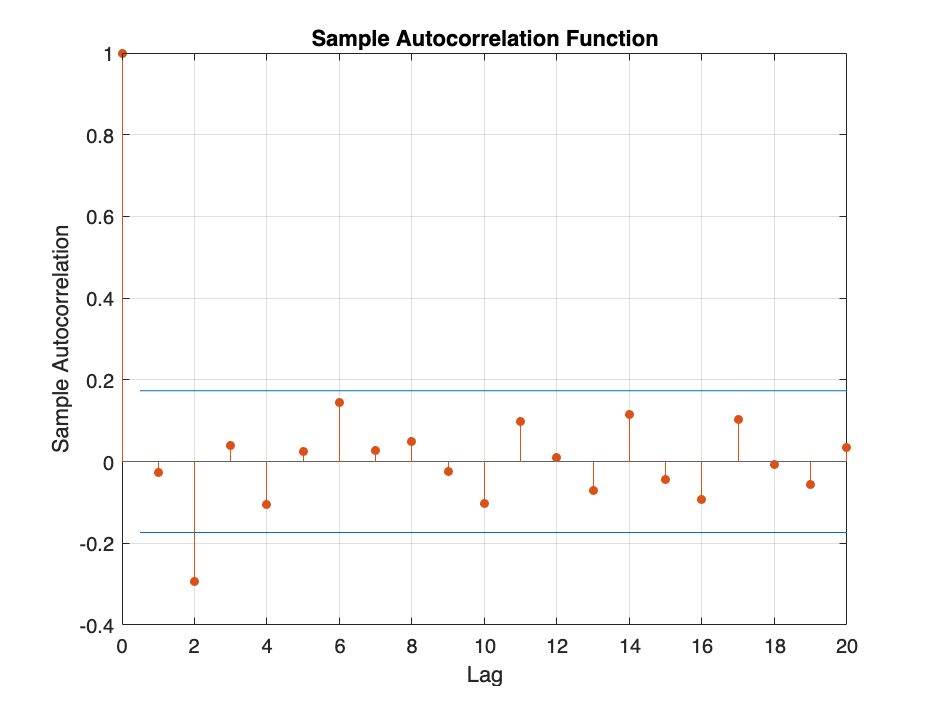

autocorr(uhat_PCECTPI)

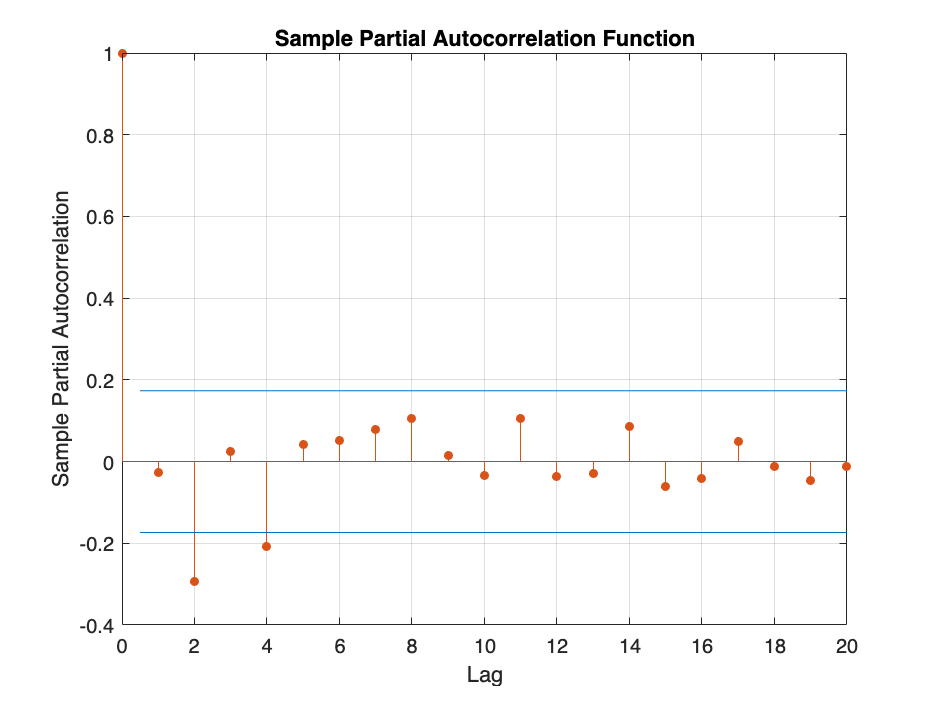

parcorr(uhat_PCECTPI)

forecast6 = fore6;
DatiProject333 = Tspread_t(103:235);
uhat_Tspread_t = DatiProject333 - forecast6;    % ref section 2
meanValue3 = mean(uhat_Tspread_t);

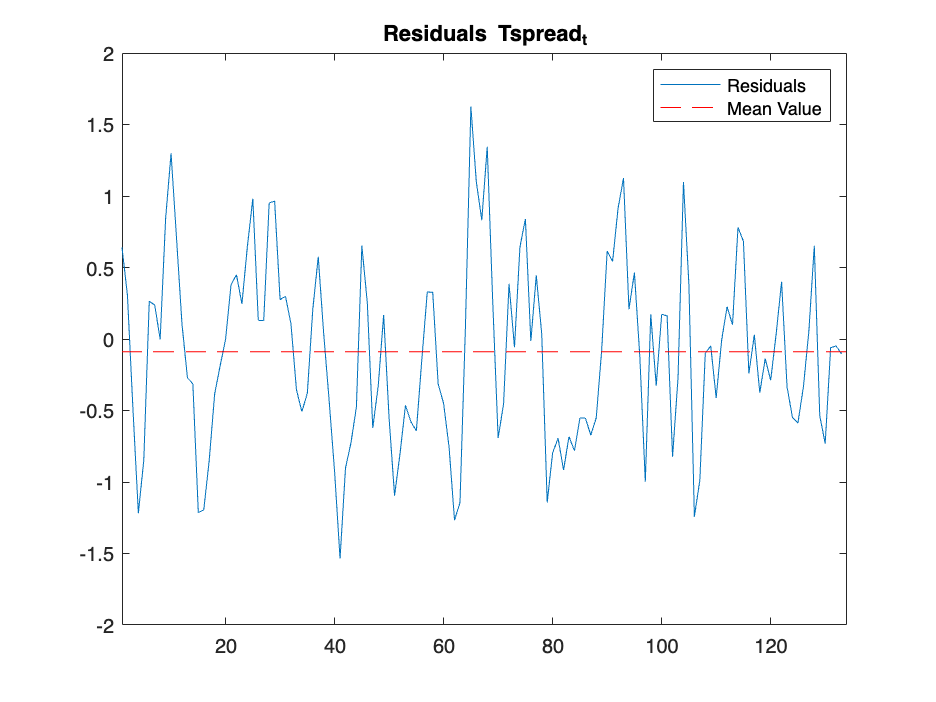

plot(uhat_Tspread_t); hold on;
title('Residuals Tspread_t');  
xlim([1 134]);
line([1, length(Tspread_t)], [meanValue3, meanValue3], 'Color', 'red', 'LineStyle', '--'); hold off % a line for the mean of the residuals
legend('Residuals', 'Mean Value');

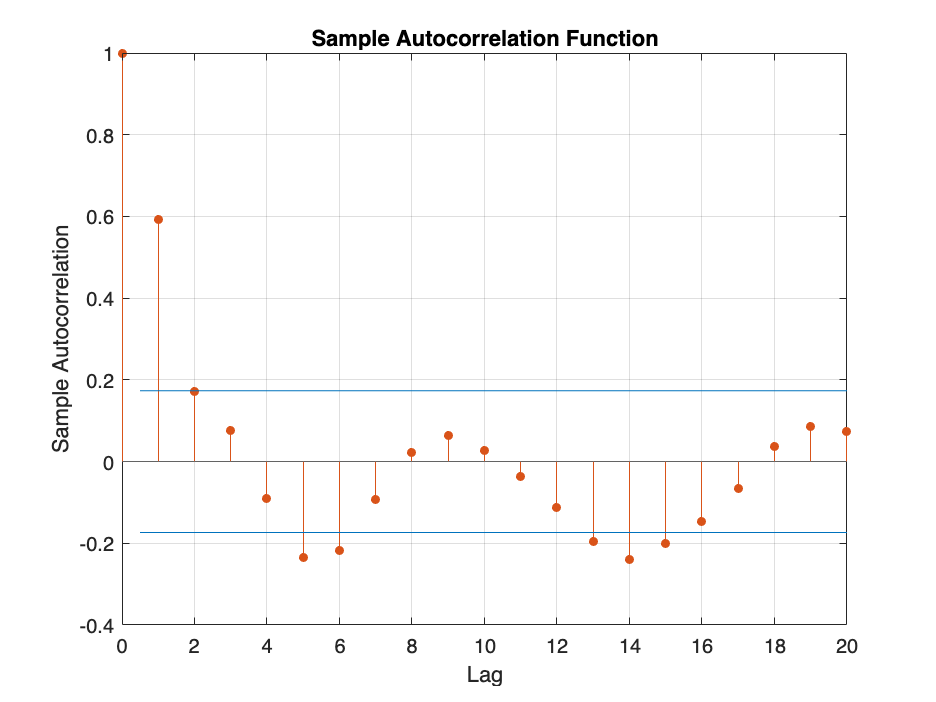

autocorr(uhat_Tspread_t)

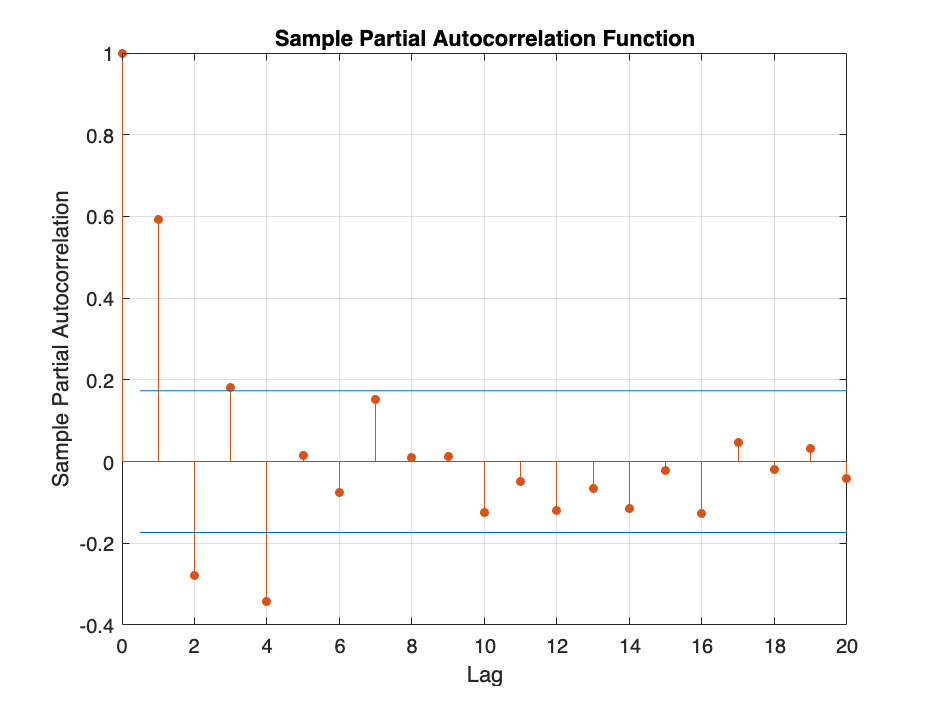

parcorr(uhat_Tspread_t)

**5) AR(4)-X model for Δyt**

An AR(4)-X model for Δyt that includes the lag of the first principal component ( ˆ F1t−1) as exogenous variable.  ˆ F1t−1 is computed using all the variables in the FRED-QD database, except GDPC1t. (sheet: DataForFactors)

You can apply PC analysis directly to the series in the sheet ”DataForFactors”. These have already been transformed to stationarity, but you have to standardize them (zero mean, unit variance).

% Load variables
DatiProjectS1_1 = load("/Users/beatricecagnin/Documents/MATLAB/DatiProjectS1.mat");
DatiProjectS12 = DatiProjectS1_1.DatiProjectS1;
clear DatiProjectS1_1;

% Display results
DatiProjectS12

DatiProjectS12 = 254×246 table
       Time          PCECC96        PCDGx         PCESVx        PCNDx         GPDIC1         FPIx       Y033RC1Q027SBEAx      PNFIx          PRFIx       A014RE1Q156NBEA      GCEC1       A823RL1Q225SBEA     FGRECPTx        SLCEx        EXPGSC1       IMPGSC1        DPIC96         OUTNFB        OUTBS         OUTMS        INDPRO       IPFINAL      IPCONGD        IPMAT        IPDMAT        IPNMAT      IPDCONGD     IPB51110SQ     IPNCONGD       IPBUSEQ<

head(DatiProjectS12)

       Time          PCECC96        PCDGx         PCESVx        PCNDx         GPDIC1         FPIx       Y033RC1Q027SBEAx      PNFIx         PRFIx       A014RE1Q156NBEA      GCEC1       A823RL1Q225SBEA     FGRECPTx        SLCEx        EXPGSC1       IMPGSC1        DPIC96         OUTNFB        OUTBS         OUTMS        INDPRO       IPFINAL      IPCONGD        IPMAT       IPDMAT        IPNMAT      IPDCONGD     IPB51110SQ     IPNCONGD      IPBUSEQ      IPB51220SQ</

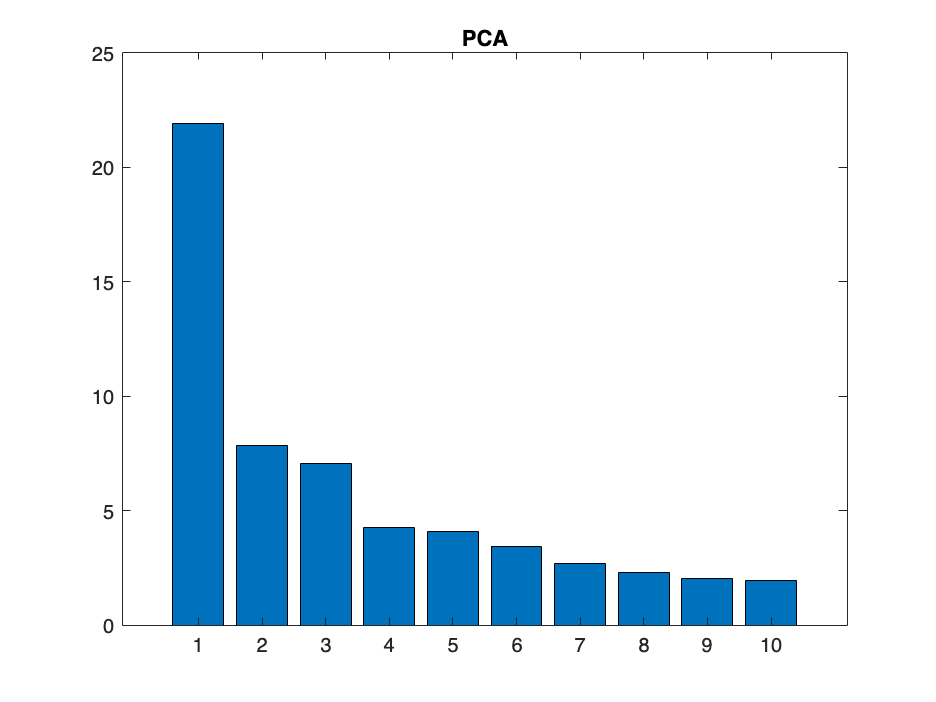

Table=removevars(DatiProjectS12,{'Time'});
X = table2array(Table);
% Standardize numerical data
Xs = zscore(X); % standardize
Xt = Xs;
[coeff,F,~,~,explained] = pca(Xs);   % apply PC analysis to the series on the whole dataset
F1 = F(:,1);
%lag the first principal component
bar(1:10,explained(1:10));
title('PCA');

Y = Dy_t;    % sulle differenze
%wsize = 300;
%j1=wsize;
jj = 1;
fore7=NaN(T,h);

while jj < 134
    disp(T-jj)
    yy = Y(jj+1:99+jj);
    % ar model forecast for F and F2
    Fhat1 = F(:,1);
    Fhat11 = Fhat1(jj:98+jj);
    % ar-x models
    mhat1 = estimate(varm(1,4),yy,'X', F(:,1)); % AR(4)-X
    f1 = forecast(mhat1,1,yy,"X",Fhat11);
    fore7(jj+1) = f1(:,1);
    jj=jj+1;
end

   233

   232

   231

   230

   229

   228

   227

   226

   225

   224

   223

   222

   221

   220

   219

   218

   217

   216

   215

   214

   213

   212

   211

   210

   209

   208

   207

   206

   205

   204

   203

   202

   201

   200

   199

   198

   197

   196

   195

   194

   193

   192

   191

   190

   189

   188

   187

   186

   185

   184

   183

   182

   181

   180

   179

   178

   177

   176

   175

   174

   173

   172

   171

   170

   169

   168

   167

   166

   165

   164

   163

   162

   161

   160

   159

   158

   157

   156

   155

   154

   153

   152

   151

   150

   149

   148

   147

   146

   145

   144

   143

   142

   141

   140

   139

   138

   137

   136

   135

   134

   133

   132

   131

   130

   129

   128

   127

   126

   125

   124

   123

   122

   121

   120

   119

   118

   117

   116

   115

   114

   113

   112

   111

   110

   109



fore77 = fore7(2:134) + y(101:233)

fore77 =     9.0367
    9.0449
    9.0544
    9.0689
    9.0774
    9.0868
    9.0902
    9.0986
    9.1035
    9.1106


forecast7 = exp(fore77)

forecast7 = 1.0e+04 *

    0.8406
    0.8476
    0.8556
    0.8681
    0.8756
    0.8838
    0.8868
    0.8943
    0.8987
    0.9051


RMSE7 = mean((DatiProject111-forecast7).^2).^0.5 

RMSE7 = 83.9546

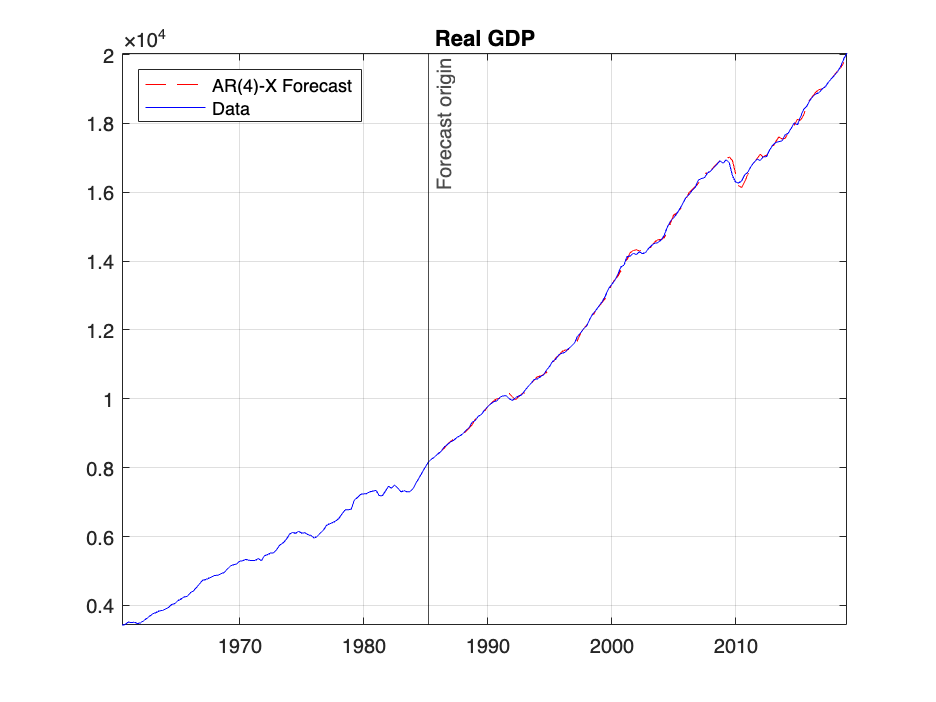

forecast77 = [nanVector;forecast7];
plot(time, forecast77, '--r'); hold on;
plot(time, DatiProject1.GDPC1, '-b'); hold off
xline(datetime("1985-03-30"), '-k', 'Forecast origin');

title('Real GDP');axis tight; grid on
legend('AR(4)-X Forecast', 'Data', 'Location','northwest')

xlim([datetime(1960,6,30)...
      datetime(2018,12,30)])

Bonus model: RANDOM WALK WITH DRIFT

m5 = arima(1,1,0);

T = length(DatiProject1.log_GDPC1);
T0 = 101;
h = 1;
fore8 = NaN(T,h);
jj = T0;
while jj < T 
    m5 = estimate(m5,DatiProject1.log_GDPC1(jj-100:jj), 'Display','off');       % estimate
    fore8(jj+1) = forecast(m5, h, DatiProject1.log_GDPC1(jj-100:jj));   % forecast
    jj = jj+1
end;

jj = 102

jj = 103

jj = 104

jj = 105

jj = 106

jj = 107

jj = 108

jj = 109

jj = 110

jj = 111

jj = 112

jj = 113

jj = 114

jj = 115

jj = 116

jj = 117

jj = 118

jj = 119

jj = 120

jj = 121

jj = 122

jj = 123

jj = 124

jj = 125

jj = 126

jj = 127

jj = 128

jj = 129

jj = 130

jj = 131

jj = 132

jj = 133

jj = 134

jj = 135

jj = 136

jj = 137

jj = 138

jj = 139

jj = 140

jj = 141

jj = 142

jj = 143

jj = 144

jj = 145

jj = 146

jj = 147

jj = 148

jj = 149

jj = 150

jj = 151

jj = 152

jj = 153

jj = 154

jj = 155

jj = 156

jj = 157

jj = 158

jj = 159

jj = 160

jj = 161

jj = 162

jj = 163

jj = 164

jj = 165

jj = 166

jj = 167

jj = 168

jj = 169

jj = 170

jj = 171

jj = 172

jj = 173

jj = 174

jj = 175

jj = 176

jj = 177

jj = 178

jj = 179

jj = 180

jj = 181

jj = 182

jj = 183

jj = 184

jj = 185

jj = 186

jj = 187

jj = 188

jj = 189

jj = 190

jj = 191

jj = 192

jj = 193

jj = 194

jj = 195

jj = 196

jj = 197

jj = 198

jj = 199

jj = 200

jj = 201

jj = 202

jj = 203

jj = 204

jj = 205

jj = 206

jj = 207

jj = 208

jj = 209

jj = 210

jj = 211

jj = 212

jj = 213

jj = 214

jj = 215

jj = 216

jj = 217

jj = 218

jj = 219

jj = 220

jj = 221

jj = 222

jj = 223

jj = 224

jj = 225

jj = 226

jj = 227

jj = 228

jj = 229

jj = 230

jj = 231

jj = 232

jj = 233

jj = 234

jj = 235

% rmse = mean((A-F).^2).^0.5
DatiProject11 = DatiProject.GDPC1(102:235);
forecasts8 = exp(fore8(102:235));

rmse8 = mean((DatiProject11-forecasts8).^2).^0.5

rmse8 = 82.0144

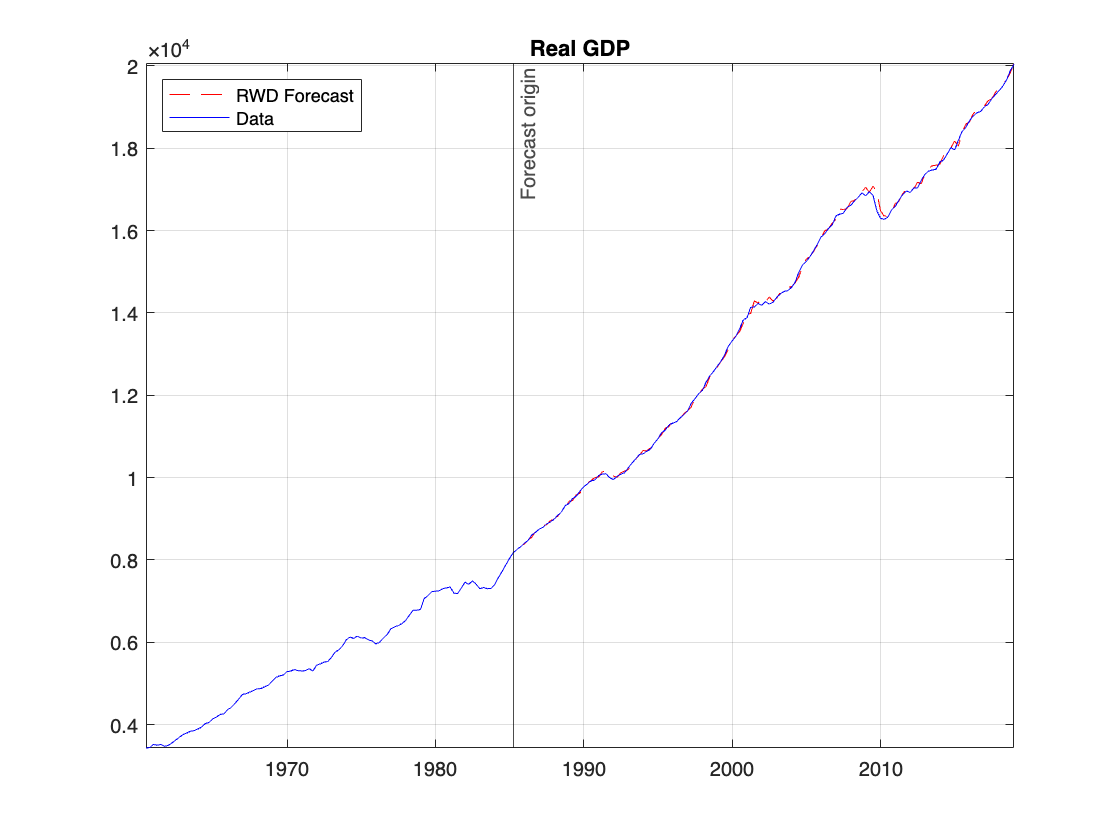

forecasts8 = [nanValue;forecasts8];
plot(time, forecasts8, '--r'); hold on;
plot(time, DatiProject1.GDPC1, '-b'); hold off
xline(datetime("1985-03-30"), '-k', 'Forecast origin');

title('Real GDP'); axis tight; grid on
legend('RWD Forecast', 'Data', 'Location','northwest')

xlim([datetime(1960,6,30)...
      datetime(2018,12,30)])